1a)

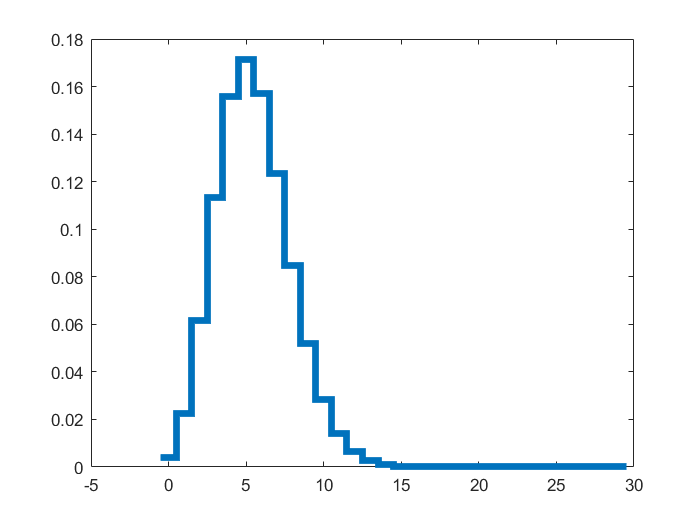

clc; close all; clear all;
background = 5.5;
gammaRays = 25;
x = 0:30;
poisson = makedist("Poisson", 'lambda',background);
stairs(x-0.5,pdf(poisson,x),"LineWidth",4);

A = pdf(poisson,x);
L = (0:(length(A)-1));
stairs(L-0.5,A,"LineWidth",4);

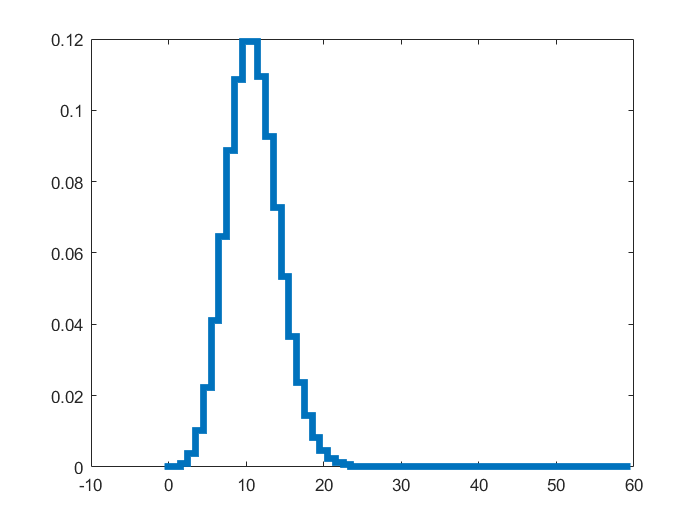

B = conv(A,A);
L = (0:(length(B)-1));
stairs(L-0.5,B,"LineWidth",4);

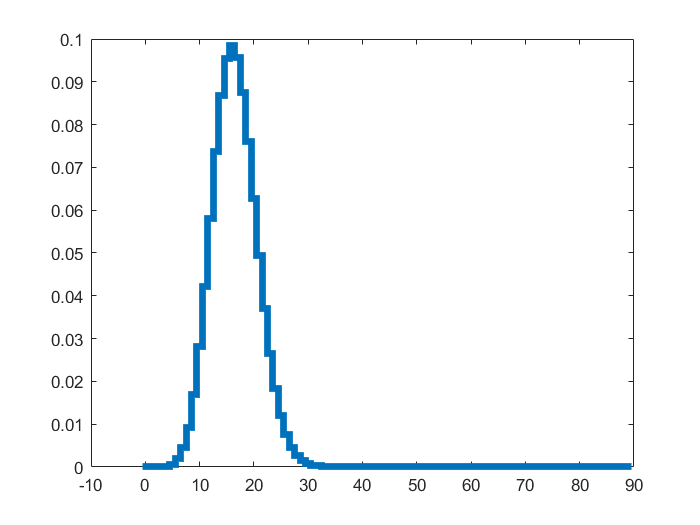

C = conv(A,B);
L = (0:(length(C)-1));
stairs(L-0.5,C,"LineWidth",4);

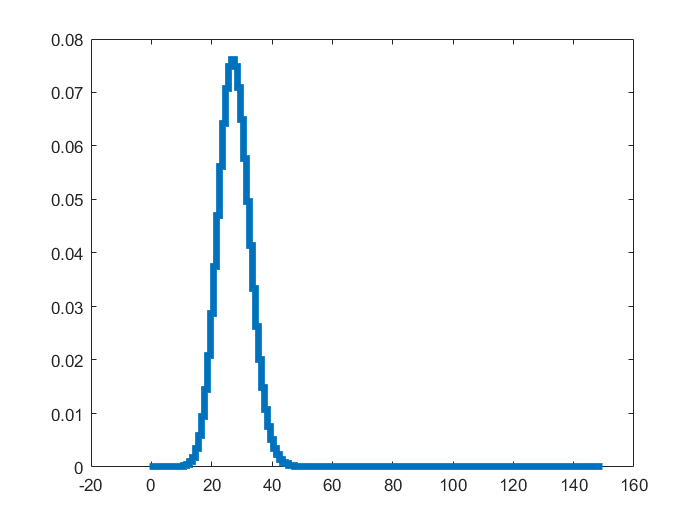

D = conv(B,C);
L = (0:(length(D)-1));
stairs(L-0.5,D,"LineWidth",4);

1b)

day5 = A;
for i=1:4
    day5 = conv(A,day5);
end
L = (0:(length(day5)-1));
stairs(L-0.5,day5,"LineWidth",4);

1c)

%szednoajisEASY

1d)

N = 25;
gammaRaysN = gammaRays*N;

2a)

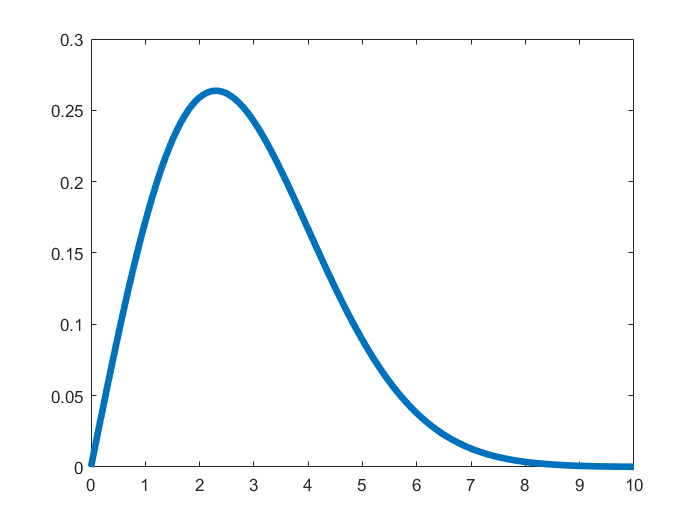

x = linspace(0,10,1000);
rayl = makedist("Rayleigh",'b',2.3);
plot(x,pdf(rayl,x),"LineWidth",4);

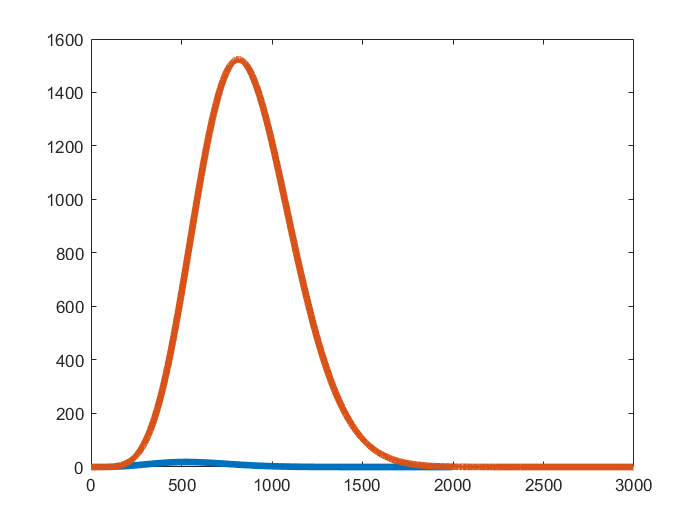

raypdf = pdf(rayl,x);
sumAvg3 = raypdf;
for i=1:2
    sumAvg3 = conv(raypdf,sumAvg3);
    L2 = (0:(length(sumAvg3)-1));
    plot(L2,sumAvg3,"LineWidth",4);
    hold on;
end
hold off;

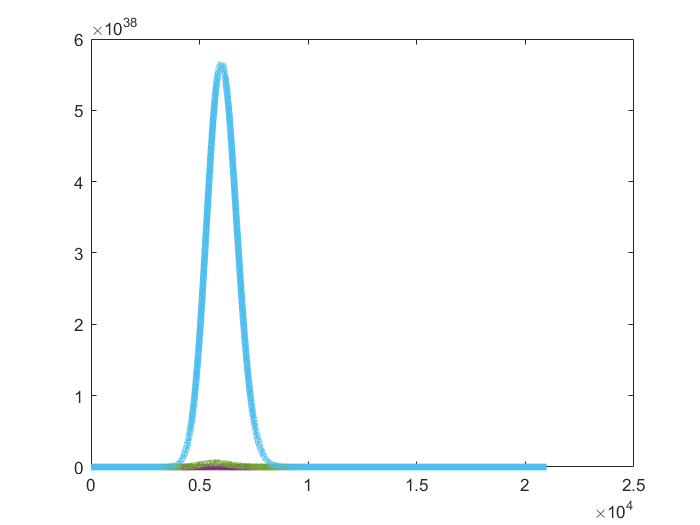

sumgauss = raypdf;
for i=1:20
    sumgauss = conv(raypdf,sumgauss);
    L2 = (0:(length(sumgauss)-1));
    plot(L2,sumgauss,"LineWidth",4);
    hold on;
end
hold off;

2b) It looks like the general shape remains the same however it becomes more pronounced when seen at a larger scale. The more sums you do, the more it looks like a gaussian. It starts looking like one after the first sum.

3a)

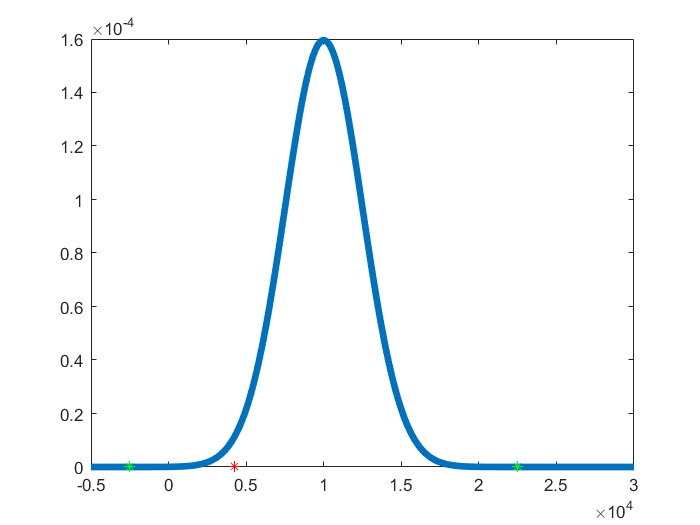

x = linspace(-5000,30000,10000000);
Y = 4.24543*10^3;
gaus = makedist("Normal",'mu',10000,'sigma',2500);
plot(x,pdf(gaus,x),"LineWidth",4);
hold on
plot(Y,0,'r*');
plot(2500*5+10000,0,'g*');
plot(10000-2500*5,0,'g*');
hold off

prob = cdf(gaus,Y,'upper');
sigmaY = norminv(prob)

sigmaY = 2.3018

In this case, this is not a discovery as the sigma of the detected pixel is 2.3018 which is less than 5.

3b) What's the probability that a signal is detected in the background.

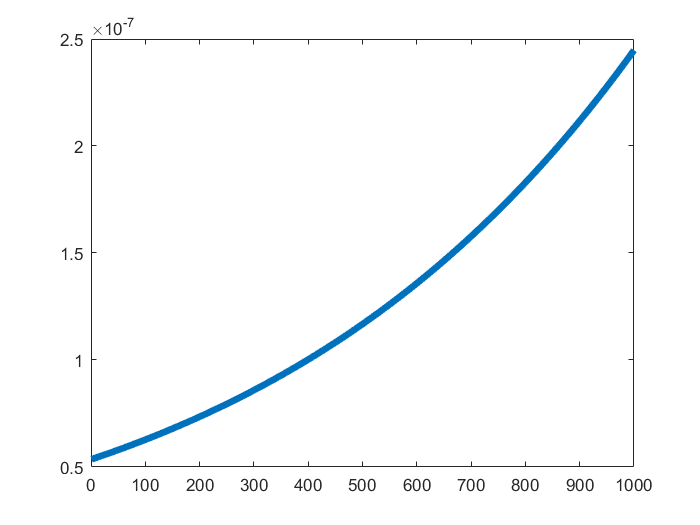

pixels = 1:1000;
Y = 3.42231*10^2;
gaus = makedist("Normal",'mu',10000,'sigma',2500);
plot(pixels,pdf(gaus,pixels),"LineWidth",4);

prob = cdf(gaus,Y,'upper')

prob = 0.9999

3c)

sigmaY = norminv(prob)

sigmaY = 3.8631

This is likely not a signal.

4a)

sigmaReqV1 = 5*2500+10000

sigmaReqV1 = 22500

4b)

sigmaReqV2 = 5*2500+1000

sigmaReqV2 = 13500

4c) The sensitivity penalty due to a low number of trials is low because you're not working with huge amounts of data so it is easier to sift through.

4d) If you significantly increase the number of trials, 5-sigma sensitivity would increase because the criteria for a "signal" is much more stringent now. Alternatively if you were to lower the number of trials, 5-sigma sensitivity would decrease since the criteria for a signal is now less stringent.

EC) If we had a different distribution, I think that it would not really affect the sensitivity penalty if you did enough trials as it would look more like a gaussian as shown above in problem 2a.